# Actividad 5

## Robot 2

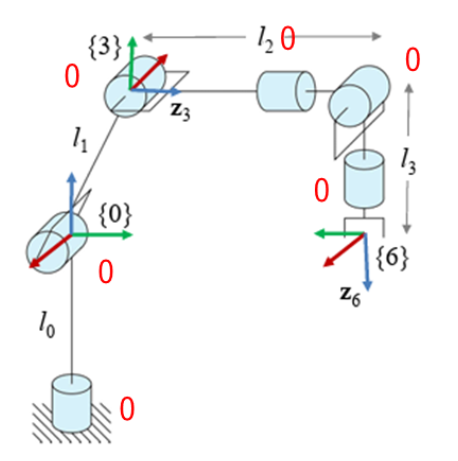

%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas
syms th1(t) th2(t) th3(t) th4(t) th5(t) th6(t) t l0 l1 l2 l3 l4 l5

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0 0 0 0 0];

%Creamos el vector de coordenadas articulares
Q= [th1, th2, th3, th4, th5, th6];
%disp('Coordenadas generalizadas');
%pretty (Q);

%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
%disp('Velocidades generalizadas');
%pretty (Qp);
%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);


%Articulación 1
%Articulación 1 a Articulación 2
%Posición de la articulación 1 a 2
P(:,:,1)= [0;0;l0];
%Matriz de rotación de la junta 1 a 2
R(:,:,1)= rotacion_z(th1);


%Articulación 2
%Articulación 2 a Articulación 3
%Posición de la articulación 2 a 3
P(:,:,2)= [0;0;l1];
%Matriz de rotación de la junta 2 a 3
R(:,:,2)=  rotacion_z(th2)*rotacion_y(-90)*rotacion_z(-90);

Aquí es el mismo caso que la pagina 2.


%Articulación 3 
%Posición de la articulación 3 respecto a 2
P(:,:,3)= [0; 0;l2];

%Matriz de rotación de la junta 3 respecto a 2  0º
R(:,:,3)=  rotacion_z(th3);
%Articulación 3 

%Posición de la articulación 4 respecto a 3
P(:,:,4)= [0; 0;l3];

%Matriz de rotación de la junta 5 respecto a 4 0º
R(:,:,4)=  rotacion_z(th4)*rotacion_y(-90);

%Posición de la articulación 5 respecto a 4
P(:,:,5)= [0; 0;l4];

%Matriz de rotación de la junta 5 respecto a 4 0º
R(:,:,5)=  rotacion_z(th5)*rotacion_z(90)*rotacion_y(-90);
%Posición de la articulación 5 respecto a 4
P(:,:,6)= [0; 0;l5];

%Matriz de rotación de la junta 5 respecto a 4 0º
R(:,:,6)=  rotacion_z(th5)*rotacion_z(90)*rotacion_y(-90);
%Creamos un vector de ceros
Vector_Zeros= zeros(1, 6);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

Error using catMany>checkDimensions (line 53)
Dimensions of objects being concatenated must match.

Error in catMany (line 12)
[resz, ranges] = checkDimensions(sz, dim);

Error in <a href="matlab:matlab.lang.internal.introspective.errorDocCallback('sym/vertcat', 'C:\Users\alfre\Documents\toolbox\symbolic\symbolic\@sym\vertcat.m', 20)" style="font-weight:bold">sym/vertcat<

%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str))
    T(:,:,i)= simplify(T(:,:,i))
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end


%Calculamos el jacobiano lineal de forma diferencial
%disp('Jacobiano lineal obtenido de forma diferencial');
%Derivadas parciales de x respecto a th1 y th2
Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), th2);
Jv13= functionalDerivative(PO(1,1,GDL), th3);
%Derivadas parciales de y respecto a th1 y th2
Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), th2);
Jv23= functionalDerivative(PO(2,1,GDL), th3);
%Derivadas parciales de z respecto a th1 y th2
Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), th2);
Jv33= functionalDerivative(PO(3,1,GDL), th3);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13;
              Jv21 Jv22 Jv23;
              Jv31 Jv32 Jv33]);
%pretty(jv_d);


%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 %Casos: articulación rotacional
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     %Para las juntas prismáticas
     elseif RP(k)==1 %Casos: articulación prismática
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);


Aqui podemos ver las velocidades lineales y angulares obtenidas de los jacobianos. Pudiendo observar que en el caso de las velocidades angulares cada articulación afecta la orientación del efector final es decir de la parte final de la articulación 3.

disp('Velocidad lineal obtenida mediante el Jacobiano lineal');
V=simplify (Jv_a*Qp');
disp(V);
disp('Velocidad angular obtenida mediante el Jacobiano angular');
W=simplify (Jw_a*Qp');
disp(W);


%funciones auxiliares para rotaciones
function Rx = rotacion_x(theta)
   
    Rx = [1,         0,           0;
          0, cosd(theta), -sind(theta);
          0, sind(theta),  cosd(theta)];
end


function Ry = rotacion_y(theta)
    % ROTACION_Y - Matriz de rotación alrededor del eje Y
    Ry = [ cosd(theta), 0, sind(theta);
                  0, 1,          0;
          -sind(theta), 0, cosd(theta)];
end

function Rz = rotacion_z(theta)
    % ROTACION_Z - Matriz de rotación alrededor del eje Z
    Rz = [cosd(theta), -sind(theta), 0;
          sind(theta),  cosd(theta), 0;
                 0,            0, 1];
end

